clear;
n=2;
coordinate=sym("u%d",[n,1]);
X=[ cos(coordinate(2))*sin(coordinate(1))
 sin(coordinate(2))*sin(coordinate(1))
cos(coordinate(1))];
uinterval=[0,pi];
vinterval=[0,2*pi];
hh=hjs("n",n,"coordinate",coordinate,"X",X);

hh();
hh.connection

$$\left(\begin{array}{cc} 0 & 0\\ 0 & \frac{\cos\left(u_{1}\right)}{\sin\left(u_{1}\right)} \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & -\cos\left(u_{1}\right)\,\sin\left(u_{1}\right)\\ \frac{\cos\left(u_{1}\right)}{\sin\left(u_{1}\right)} & 0 \end{array}\right)$$

hh.g

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & {\sin\left(u_{1}\right)}^{2} \end{array}\right)$$

hh.curvature_tensor();
hh.Scalar_curvature

$$ans = 2$$

hh.Gauss_curvature

$$ans = 1$$

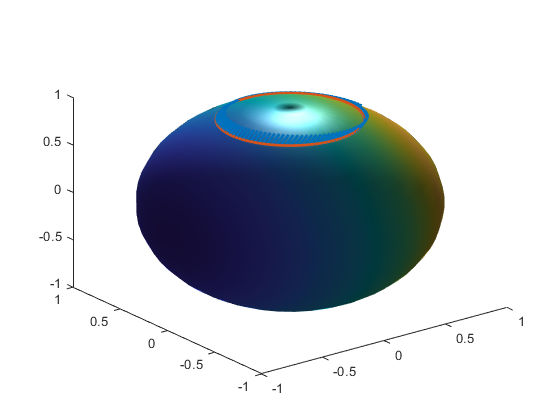

hh.drawmesh(uinterval,vinterval,0);
hold on;
syms t;
u(t)=[0.5;t];
% hh.scale=0;
hh.parallel_transport(u,[0;2*pi],[1,0],100);

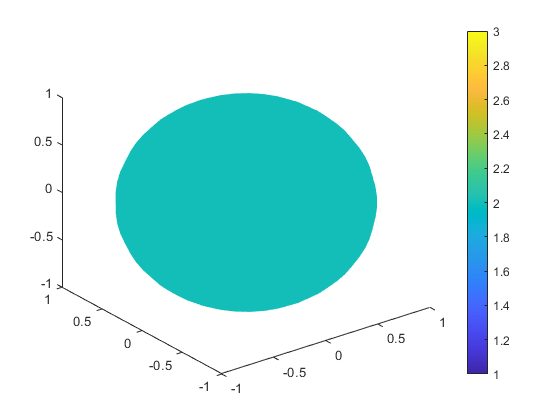

figure;
hh.drawmesh(uinterval,vinterval,1);

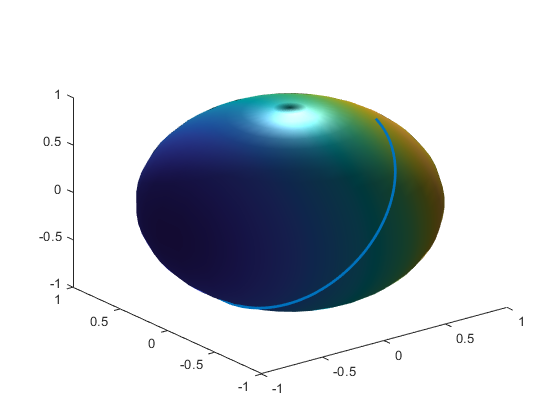

figure;
hh.drawmesh(uinterval,vinterval,0);
hold on;
hh.geodesic([0,40],[0.1, 0.1, 1, 1],100);